% Função da soma
function[x,t] = SomaFourier(Ta, f0, np, a, b)
    T0=1/f0;
    t = 0:Ta:np*T0-Ta;
    L = length(a);
    x = 0;

    for k=1:L
        x = x + a(k)*cos(2*pi*(k-1)*f0*t) + b(k)*sin(2*pi*(k-1)*f0*t);

    end

end
   

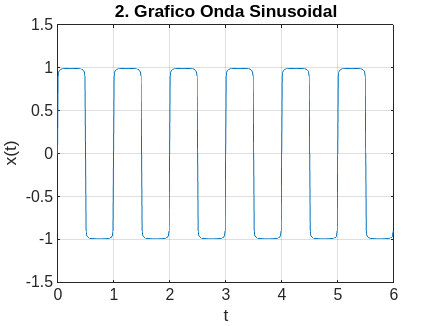


% 2
f0 = 1;
k = 100;
Fa = 100; %= 1/Ta = 0.01
ak = zeros(1,k);
bk = zeros(1,k-1);

impares = 1:2:k-1;
bk(impares) = 4./(impares*pi);
bk = [0,bk];

[x, t]  = SomaFourier(1/Fa, f0, 6, ak, bk);
figure(1);

plot(t,x);

ylim([-1.5,1.5]);
xlabel('t');
ylabel('x(t)');
grid on;

% 3
function[ak,bk] = CoefFourier(Ta,T,x,K) 
    ak=zeros(1,K);
    bk=zeros(1,K);
    N=T/Ta;
    f=1/T;
    
    for  n=1:N
        ak(1)=ak(1)+(1/N)*x(n);
    end

    for k=2:K
        for n=1:N
            ak(k)=ak(k) + 2/N*x(n)*cos(2*pi*(k-1)*f*n*Ta);
            bk(k)=bk(k) + 2/N*x(n)*sin(2*pi*(k-1)*f*n*Ta);
        end
    end
end


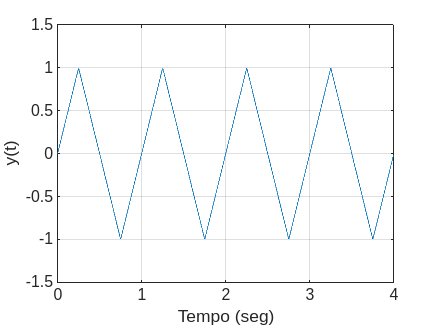

% 4
Ta=0.001;
Np=4;
K=100;
T=1; 
f=1/T;
t=0:Ta:T;

x=sawtooth(2*pi*f*t+pi/2,1/2);

[ak,bk]=CoefFourier(Ta,T,x,K);
[x,t]=SomaFourier(Ta,f,Np,ak,bk);

figure(1);

plot(t,x);

ylim([-1.5,1.5]);
xlabel('Tempo (seg)');
ylabel('y(t)');
grid on;